# Blink Signal Removal From EEG Using PCA and ICA

### Code Authored By: Shawhin Talebi

clear; close all; clc
warning('off')

#### Import Data

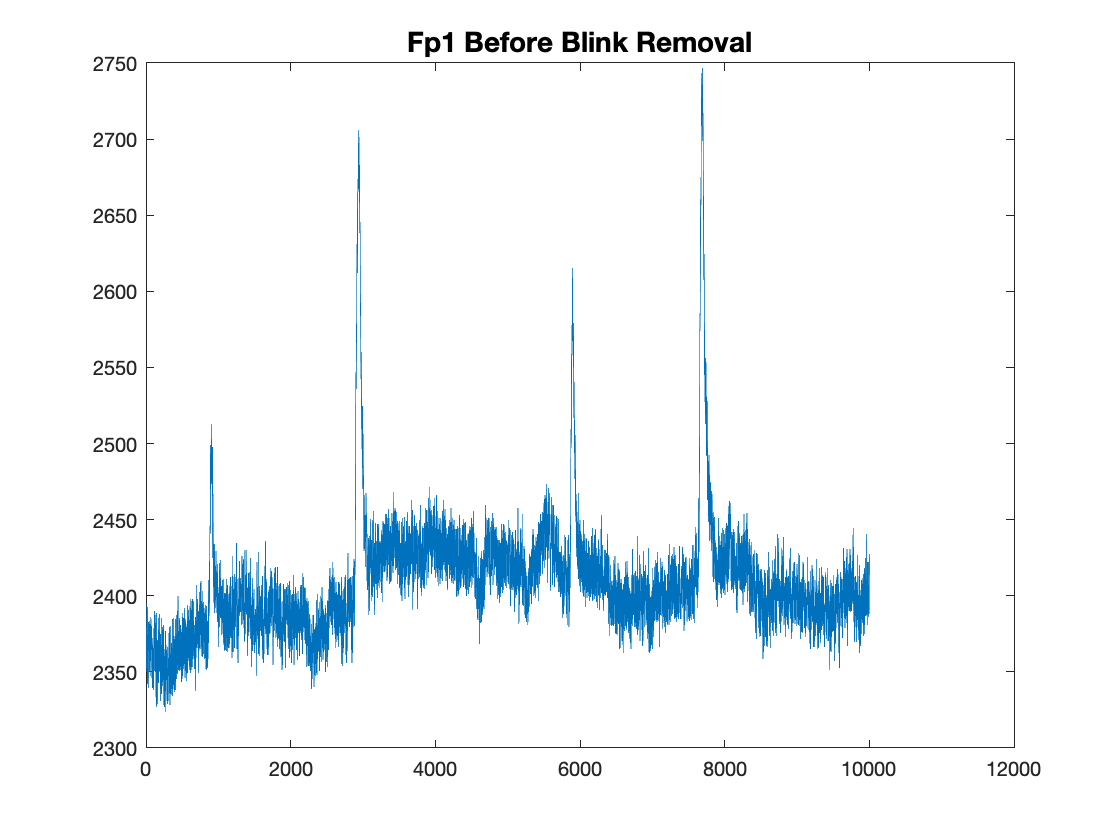

load('EEG_data')

% plot Fp1 electrode data (sits at front left part of head hear left eye)
% perturbations can be seen visually due to blinks
plot(Data(:,1))
title("Fp1 Before Blink Removal", 'FontSize', 14)

#### PCA

% DEFINE NUMBER OF PRINICPLE COMPONENTS TO KEEP
% NOTE: it is typically a good idea to try out different numbers and
% compare their total explained variation
q=21;

% PERFORM PCA
% NOTE: it is important to normalize data! (i.e. substract mean of each 
% column and divide by standard deviation. MATLAB's pca function does this 
% automatically :p
[coeff,Data_PCA,latent,tsquared,explained,mu] = pca(Data, 'NumComponents', q);

% compute and display explained variation
disp(strcat("Top ", string(q), " principle components explain ", ...
    string(sum(explained(1:q))), " of variation"))

Top 21 principle components explain 99.5134 of variation


#### ICA

% compute independent components from principle components
% train ICA model
Mdl = rica(Data_PCA, q);

% apply ica
Data_ICA = transform(Mdl, Data_PCA);

#### Plot Components

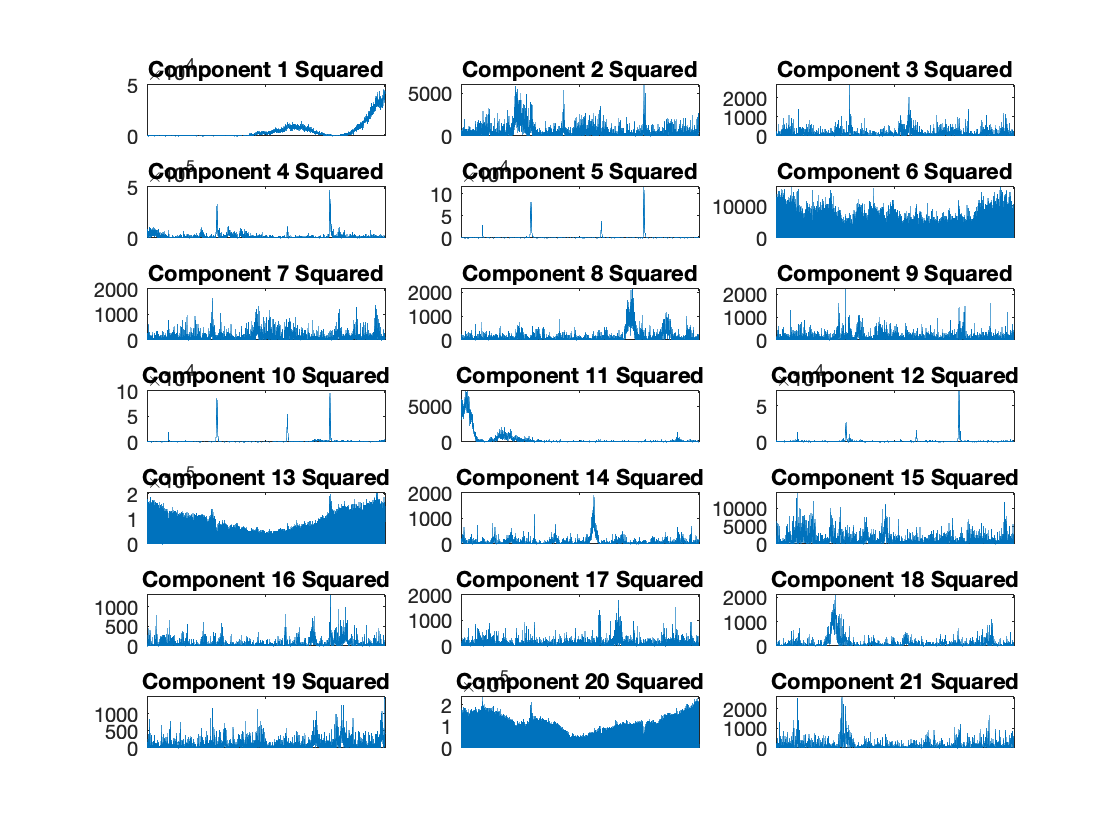

% define number of plots per column of figure
plotsPerCol = 7;

% plot components
figure(2)
for i = 1:q
    
    subplot(plotsPerCol,ceil(q/plotsPerCol),i)
    plot(Data_ICA(:,i).^2)
    title(strcat("Component ", string(i), " Squared"))
    ax = gca;
    ax.XTickLabel = {};
    
end

#### Remove Embedded Blink Information

% use heuristic to pick component corresponding to blink
Components_blink = pickBlinkComponents(Data_ICA);
disp("Blink component(s):")

Blink component(s):


disp(Components_blink)

    10    12



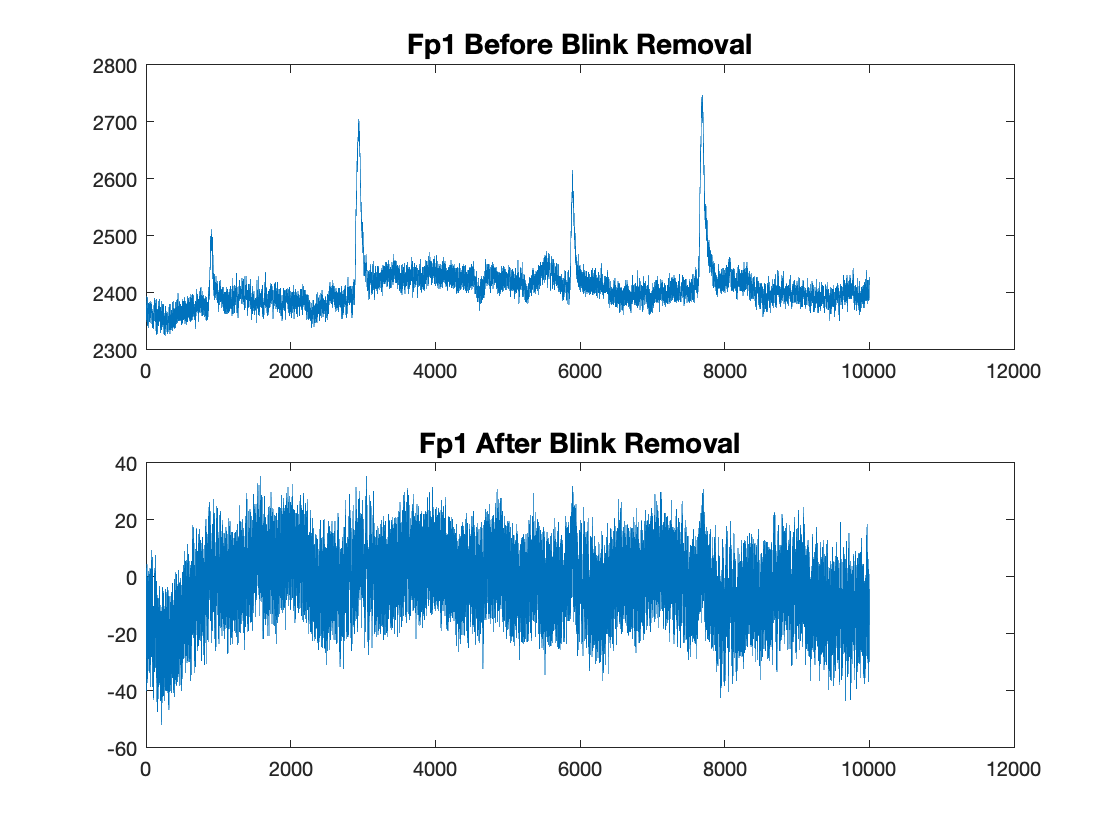


% zero all columns corresponsing to blink components
Data_ICA_noBlinks = Data_ICA;
Data_ICA_noBlinks(:,Components_blink) = ...
    zeros(length(Data_ICA), length(Components_blink));

% perform inverse ica transform
Data_PCA_noBlinks = Data_ICA_noBlinks*Mdl.TransformWeights;

% perform inverse pca transform
Data_noBlinks = Data_PCA_noBlinks*coeff';

% plot Fp1 electrode before and after
figure(3)
subplot(2,1,1)
plot(Data(:,1))
title("Fp1 Before Blink Removal", 'FontSize', 14)
subplot(2,1,2)
plot(Data_noBlinks(:,1))
title("Fp1 After Blink Removal", 'FontSize', 14)

#### Funtion Definitions

function Components_blink = pickBlinkComponents(Data_ICA)
    
    % get total number of components from input array
    [~, q] = size(Data_ICA);

    % initialize counter and output array
    i = 1;
    Components_blink = [];

    while i<q
        
        % find peaks of ith component
        % MinPeakDistance informed by average blink rate of 22 blinks/min
        % and 500 Hz sampling rate
        % MinPeakProminence defined by trial and error
        pks = findpeaks(Data_ICA(:,i), ...
            'MinPeakDistance', 1500, ...
            'MinPeakProminence', 100);
        
        % if four peaks exist choose as blink component
        if length(pks)==4
            Components_blink = [Components_blink i];
        end
        
        % increment counter
        i = i + 1;
        
    end

end